# **Dimitrios Megkos - 210034034**

***Type of problem:**** Binary classification*

***Machine Learning Algorithms:**** Random Forest vs K-Nearest Neighbour *

***Dataset:**** Wine Quality Data Set, White *[*[1]*](about:blank<#M_E10C7293>)

## *Click here to test the models on the testing set.*

#### Initialisation

clear, clc
%set rng for reproducability
rng(0);

#### Load dataset

%load the csv file into a matrix
wine = readmatrix("winequality_train.csv");
wine_test = readmatrix("winequality_test.csv");
%split features and classes
%training set
X = wine(:,1:11);
Y = wine(:,12);
%final test set
Xval = wine_test(:,1:11);
Yval = wine_test(:,12);

#### Random Forest Machine Learning Algorithm [*[2]*](about:blank<#M_0305055E>)

Call a Random Forest classifier function, without optimising hyperparameters, using random initial values. The function returns the F1 Score, the prediction Accuracy and the confusion matrix.[*[3]*](about:blank<#M_7B0179C4>) A view of a randomly selected tree from the Random Forest is also returned.

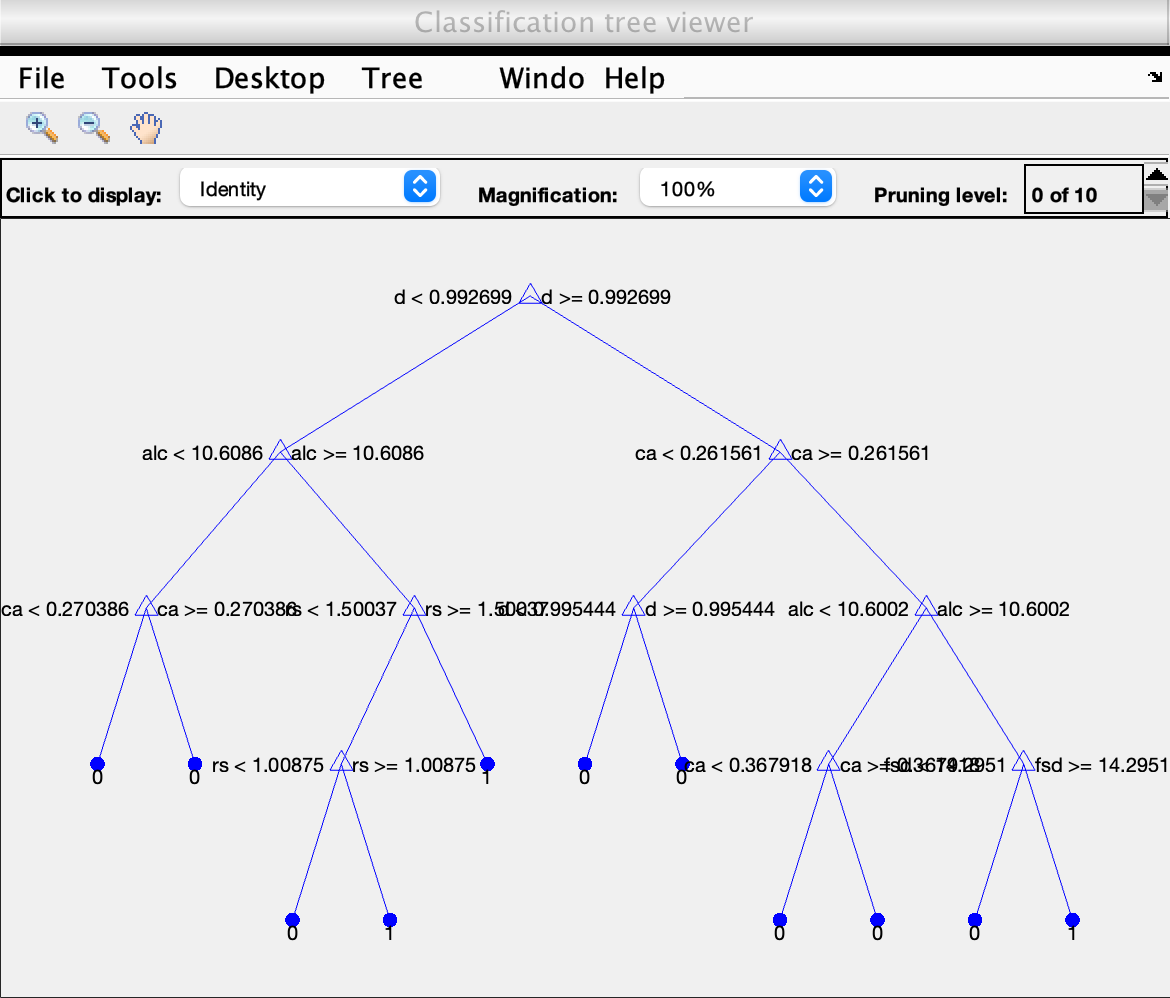

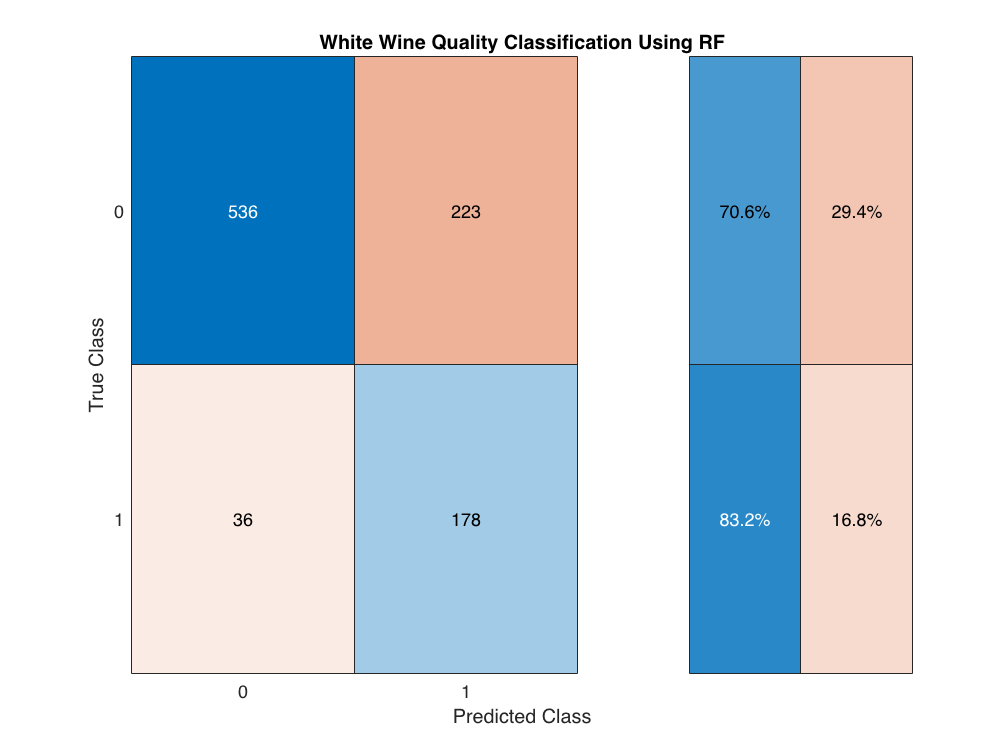

RF_F1_score = 0.7276

RF_TestAcc = 76.8984

%Custom RF without hyperparameter optimisation
tic
[RF_F1_score , RF_TestAcc] = FinalCRF(X,Y,Xval,Yval,10,1,5,"allsplits",100,true)

toc

Initial call of Random Forest classification ended in 1.15 seconds, with scores F1 Score = 0.73  and Accuracy = 77%.

#### Random Forest optimisation

Call a custom Random Forest optimisation function that goes through different combinations of hyperparameter values. The model is trained using 10-Fold Cross validation. Since Random Forest algorithm is using bootstrap aggregation, using K-Fold cross validation does not really add any extra value. However, since K-Fold cross validation will be used for K-Nearest Neighbour algorithm, in order to have a fair comparison between the two classification algorithms, it is used in Random Forest also. The function returns a combination of hyperparameter values that yields the best F1 Score. F1 Score and K-Fold Accuracy are also returned.

%optimise RF by trying different values for the hyperparameters
maxnsplits = (100:20:180); %Maximum number of splits
minlfsize = (5:5:20); %Minimum leaf size
numvarsam = (4); %Number of predictors to select at random for each split
predsel = ("allsplits"); %Predictor selector allsplits because the aim is to 
%classify and not to rank the importance of variables
numlcycl = (100); %Number of Learning Cycles for bagging
%begin optimisation
tic
[RF_TopF1_score, RF_TopKFoldAcc, BestMaxNSpl, BestMinLfSz, BestNumVSam, ...
    BestPrSl, BestNumLCycl] = OptimiseCRF(X,Y,maxnsplits,minlfsize, ...
    numvarsam,predsel,numlcycl)

RF_TopF1_score = 0.8666

RF_TopKFoldAcc = 86.5069

BestMaxNSpl = 180

BestMinLfSz = 5

BestNumVSam = 4

BestPrSl = "allsplits"

BestNumLCycl = 100

toc

Searching ended after 210 seconds. The returned scores were F1 Score = 0.87, KFold Accuracy = 86.5% for the below hyperparameters:

Maximum Number of Splits = 180, Minimum Leaf size = 5, Number of variables to sample = 4, Predictor selector = "allsplits", Number of learning cycles = 200

#### Optimised Random Forest

Call the final Random Forest classification function with the returned hyperparameter values. Model is trained on 80% of the original data and tested on the 20%.

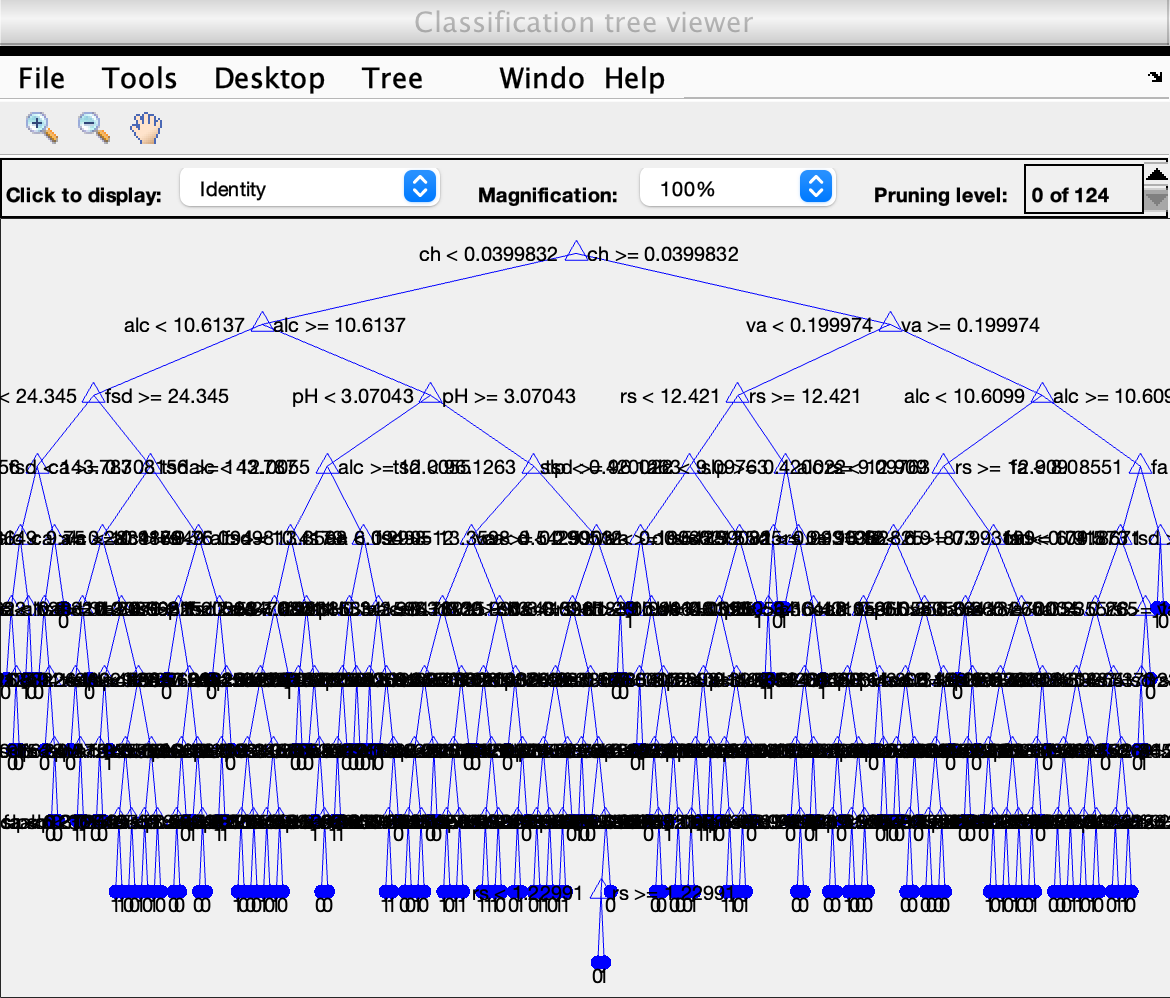

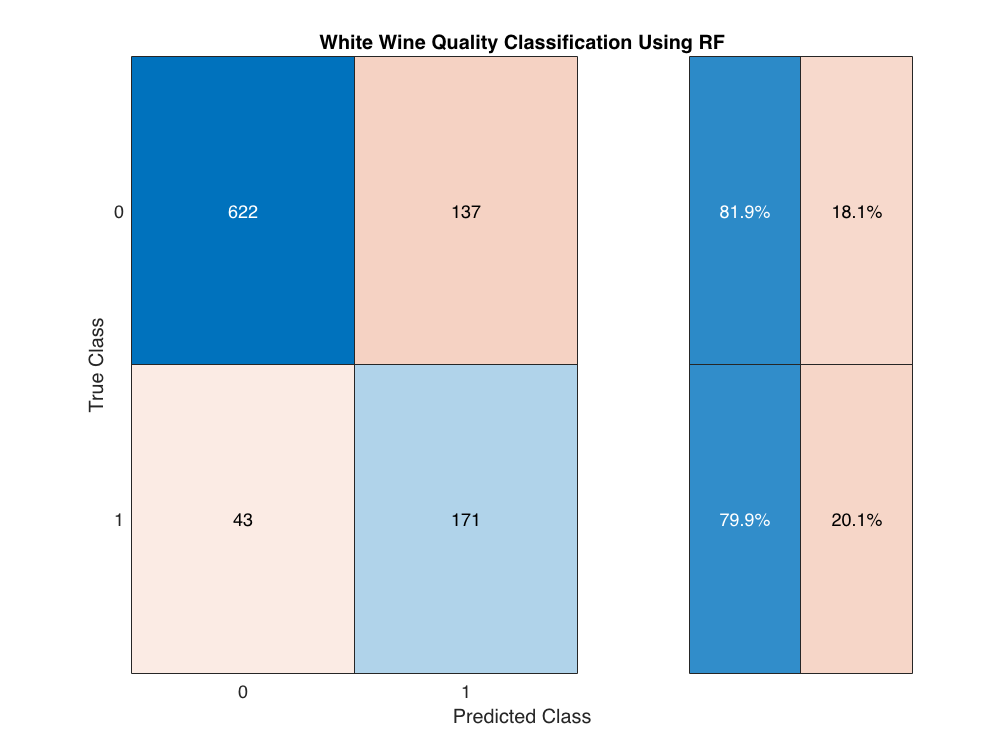

RF_F1_score = 0.7760

RF_TestAcc = 80.9282

%call final RF after optimisation of hyperparameters
tic
[RF_F1_score , RF_TestAcc, Mdl1] = FinalCRF(X,Y,Xval,Yval,180,5,4,"allsplits",100,true)

toc

Elapsed time is 2.167092 seconds.


The optimised Random Forest classification ended in 2 seconds, with scores F1 Score = 0.78 and Accuracy = 81%. Scores can be further improved by decreasing the minimum leaf size and increasing the maximum number of splits, however the risk of overfitting will also increase. Balance plays an important role in this case.

**Additional comments on Random Forest**

Although Decision Trees are simple and easy to understand algorithms, they tend to overfit [[4]](about:blank<#M_F2B7CF49>) and their accuracy is not representative of the true results. Bootstrap Aggregating (Random Forest) solves this problem by creating many Decision Trees and using aggregated results to classify the samples. This technique can take a bit more time compared to other classification algorithms, however it yields better results. Random Forest also requires much less data pre-processing than other algorithms. First, it can deal with outliers and missing values internally and second, it is not affected by class imbalance, therefore techniques like SMOTE or stratified K-Fold cross validation are not required. In addition, feature selection can be skipped since Random Forest automatically selects n random features at each learning cycle.

#### K-Nearest Neighbour [*[5]*](about:blank<#M_081FCF04>)

#### Feature selection

Univariate feature ranking for classification using chi-square tests with the built-in Matlab function fscchi2 is performed in order to discover the importance of each feature on the classification.

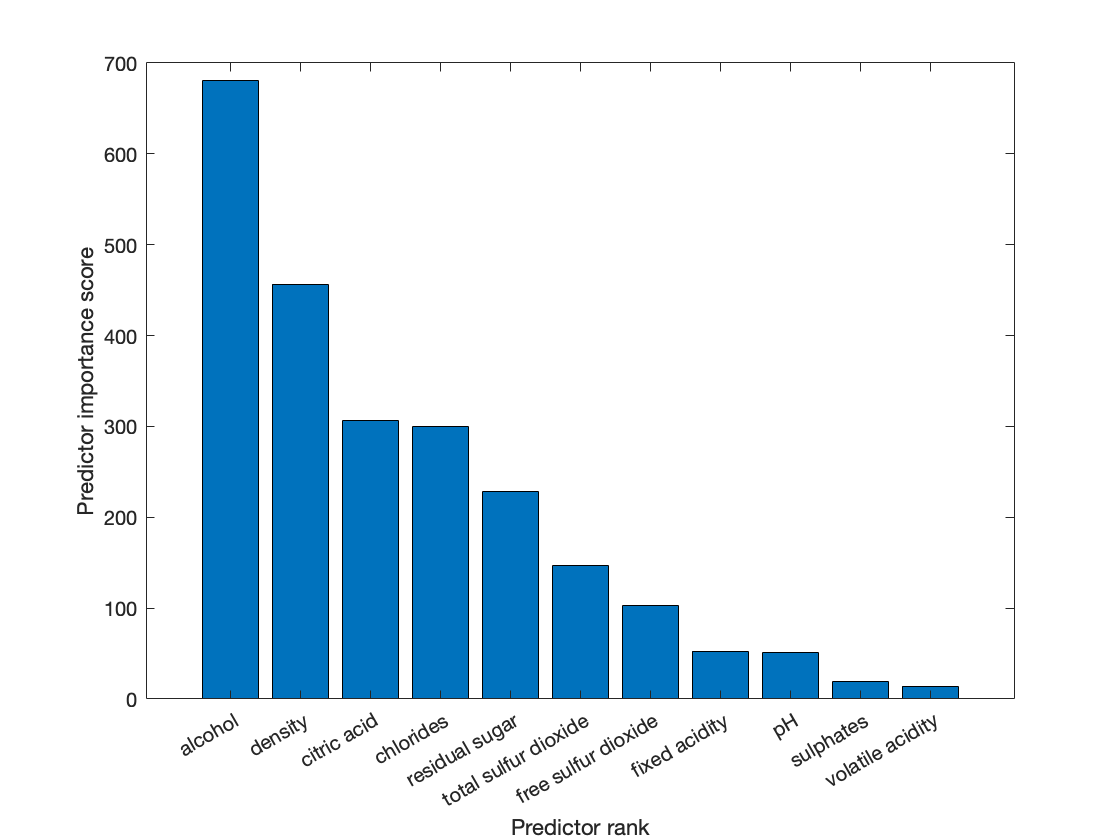

%get position along with scores for all features
[idx,scores] = fscchi2(X,Y);
%store feature labels
ftrlabel = ["fixed acidity" "volatile acidity" "citric acid" "residual sugar"...
    "chlorides" "free sulfur dioxide" "total sulfur dioxide" "density" "pH"...
    "sulphates" "alcohol"];
%plot predictor importance score
bar(scores(idx))
xlabel('Predictor rank')
ylabel('Predictor importance score')
xticklabels(ftrlabel(idx))
hold off

Check F1 Score and K-Fold Accuracy using all features first and after removing least important features, one by one.

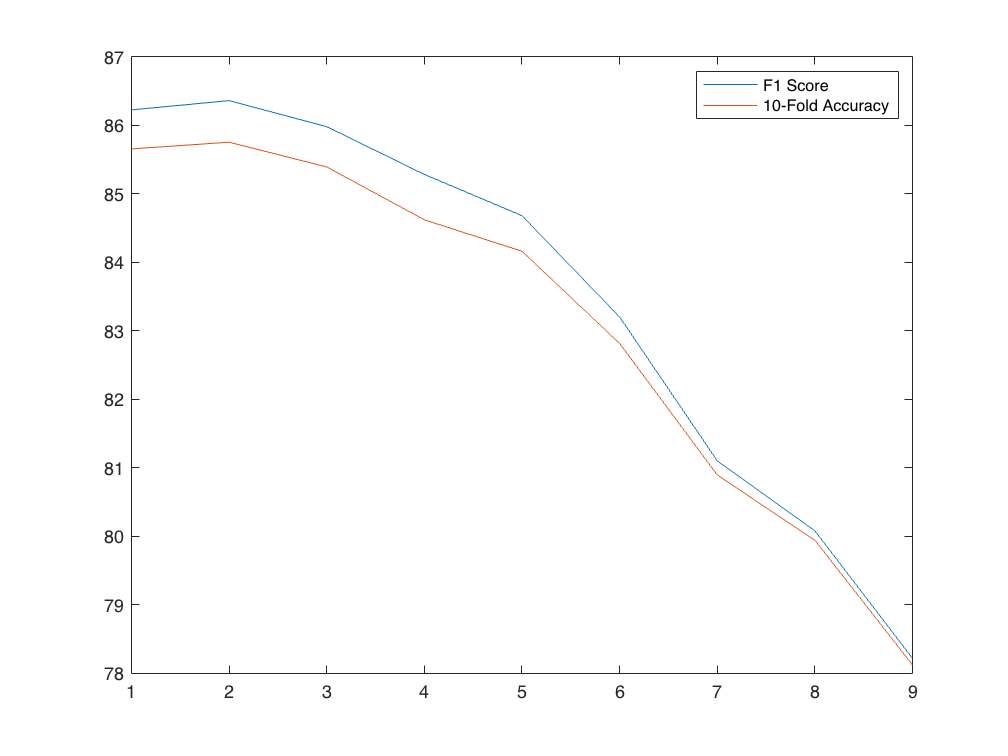

%create zeros arrays with predefined size
F1Scoreck = zeros([1 9]);
KFAccck = zeros([1 9]);
%rearange features based on importance
Xck = [X(:,11) X(:,8) X(:,3) X(:,5) X(:,4) X(:,7) X(:,6) X(:,1) X(:,9)...
    X(:,10) X(:,2)];
%get scores starting with all features first and then remove the last one
%on each iteration leaving only top two
itr = 1:1:9;
for i=itr
    %call CustomKNN without optimisation of K and distance
    [KNN_F1_score , KNN_KFoldAcc] = CustomKNN(Xck,Y,3,'minkowski');
    F1Scoreck(i) = KNN_F1_score*100;
    KFAccck(i) = KNN_KFoldAcc;
    Xck=Xck(:,1:end-1);
end
%visualise results
plot(itr,F1Scoreck)
hold on
plot(itr,KFAccck)
legend('F1 Score', '10-Fold Accuracy')
hold off

Both F1 Score and 10-Fold Accuracy improves a bit by removing the least important feature. However, in order to have a fair comparison with Random Forest, all features are going to be used for K-Nearest Neighbour classification.

#### Custom K-Nearest Neighbour

Call a custom K-Nearest Neighbour classifier function, without optimising hyperparameters, using some initial values. The function returns the F1 Score, the prediction Accuracy, and the confusion matrix.

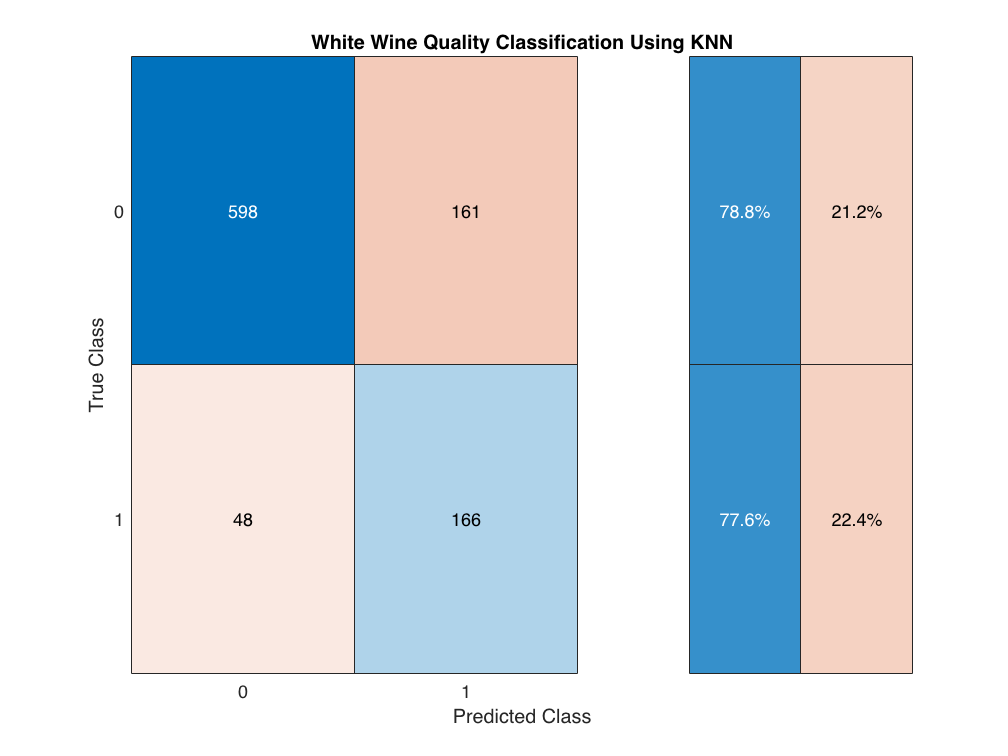

KNN_F1_score = 0.7478

KNN_FinalAcc = 78.1790

%call CustomKNN without optimisation of K and distance
tic
[KNN_F1_score , KNN_FinalAcc] = FinalCKNN(X,Y,Xval,Yval,5,'euclidean')

toc

Initial call of KNN classification ended in 0.20 seconds, with scores F1 Score = 0.75  and Accuracy = 78%.

#### K-Nearest Neighbour optimisation

Call a custom KNN optimisation function that goes through different combinations of hyperparameter values. The model is trained using 10-Fold Cross validation. The function returns combination of hyperparameter values that yields the best F1 Score. F1 Score and K-Fold Accuracy are also returned.

%optimise KNN by trying different K values and different distance functions
%generate K neighbors numbers
neighnum = (3:2:sqrt(length(X)));
%make list of distance functions to test
dist = ["spearman" "minkowski" "euclidean" "seuclidean" "mahalanobis"...
    "chebychev" "hamming" "jaccard" "cityblock" "correlation"];
%optimise Custom K-NN
tic
[KNN_TopF1_score,KNN_TopKFoldAcc,BestKN, BestDist]=OptimiseCKNN(X,Y,neighnum,dist)

KNN_TopF1_score = 0.8688

KNN_TopKFoldAcc = 86.1950

BestKN = 3

BestDist = "cityblock"

toc

Searching ended after 174 seconds. The returned scores were F1 Score = 0.87 and KFold Accuracy = 86%, using K = 3 neighbours and distance function = "cityblock".

#### Optimised K-Nearest Neighbour

Call the final K-Nearest Neighbour classification function with the returned hyperparameter values. Model is trained on 80% of the original data and tested on the 20%. The function returns the F1 Score, the prediction Accuracy, and the confusion matrix.

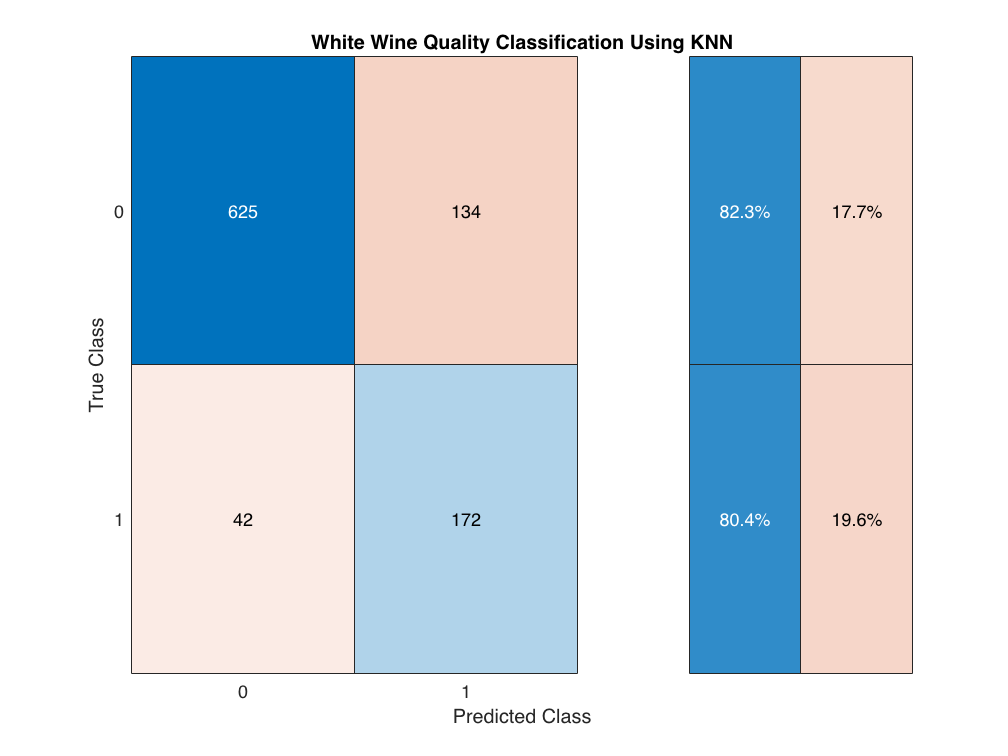

KNN_F1_score = 0.7803

KNN_FinalAcc = 81.3595

%call final K-NN with optimised hyperparameters
tic
[KNN_F1_score , KNN_FinalAcc, Mdl2] = FinalCKNN(X,Y,Xval,Yval,3,'cityblock')

toc

The optimised KNN classification ended in 0.18 seconds, with scores F1 Score = 0.78 and Accuracy = 81%.

**Additional comments on K-Nearest Neighbour**

KNN is a fast and fairly simple classification algorithm however, a couple of extra steps are required for it to be optimised:

1) KNN requires the data to be standardized beforehand, since it's classifying samples based on calculated distances 

2) KNN is not good at dealing with class imbalance and is affected by the Accuracy Paradox. As a result, extra metrics need to be calculated to evaluate the model and in order to be better trained, either extra synthetic data have to be created for the imbalanced class or Stratified K-Fold Cross validation partitioning needs to be done, which creates K number of folds, each fold being class balanced

**Additional comments on the custom optimisation function**

Matlab has a built-in technique that does automatic hyperparameter optimisation for machine learning algorithms. While this is a strong tool to have, it has certain limitations since there is not much control in the selection and values of the hyperparameters that are being tested.

The custom optimisation function that is being used for both algorithms, though the way it is searching for the best combination of hyperparameters can be considered unconventional and time consuming, is more versatile since it gives the option of which hyperparameters to change and which values to go through.

#### Random Forest vs K-Nearest Neighbour on predicting a good quality wine

Both models did a fairly good job in predicting a good quality wine. In order to have a fair comparison, same techniques were used during data pre-processing, training and evaluating for both models. 

Random Forest does a better job in handling both categorical and numerical data, class imbalance, outliers, and missing values compared to K-Nearest Neighbour. It can almost work out of the box with minimum pre-processing. Furthermore, it is more versatile due to the higher number of available optimisable hyperparameters (e.g. maximum number of splits, minimum leaf size, number of variables to sample, predictor selector and number of learning cycles) compared to K-Nearest Neighbour (number of K-neighbours, distance function). However, this also makes Random Forest harder to fine tune and more time consuming since it has to go through a much higher number of iterations to find the best combination of hyperparameters.

K-Nearest Neighbour might not have the same flexibility that Random Forest has in regard to hyperparameter tuning, yet it requires significantly less amount of time to find the best combination of hyperparameters. It is an easy to use and understand algorithm, however, unlike Random Forest, it cannot handle both categorical and numerical predictors, class imbalance, outliers, and missing values internally thus, the data need to be cleaned accordingly beforehand.

The below confusion matrices show that K-Nearest Neighbour did a slightly better job in finding both the **not good (0)** wines and the **good (1)** wines, compared to Random Forest. More specifically, Random Forest correctly classified **81.9% not good (0)** and **79.9% good (1)**, while K-Nearest Neighbour correctly classified **82.3% not good (0)** and **80.4% good (1)**.

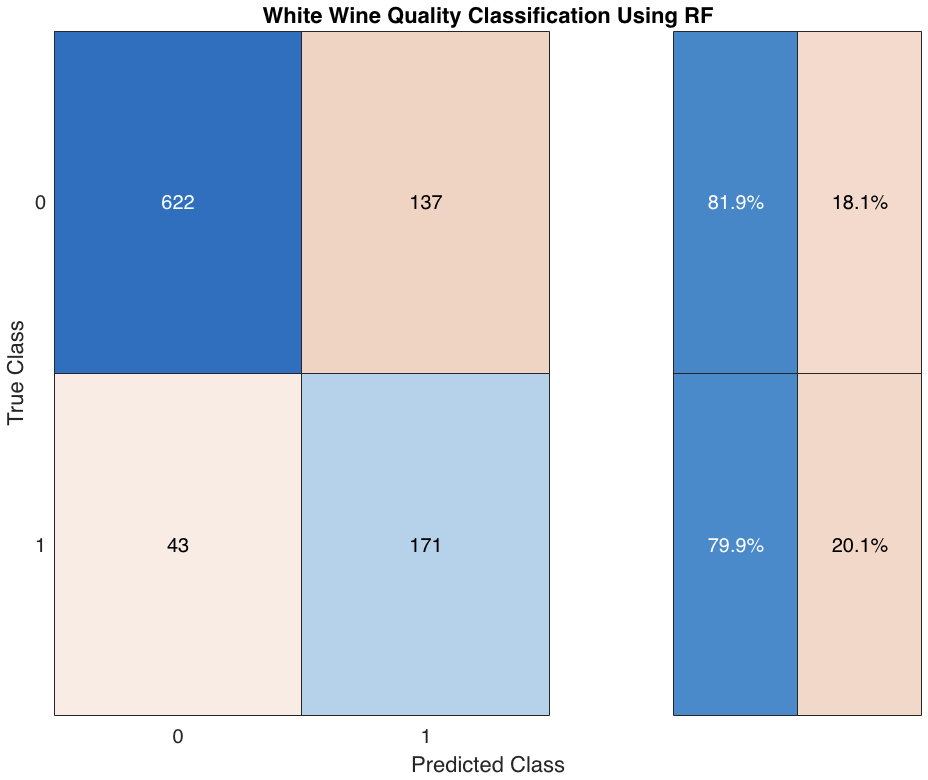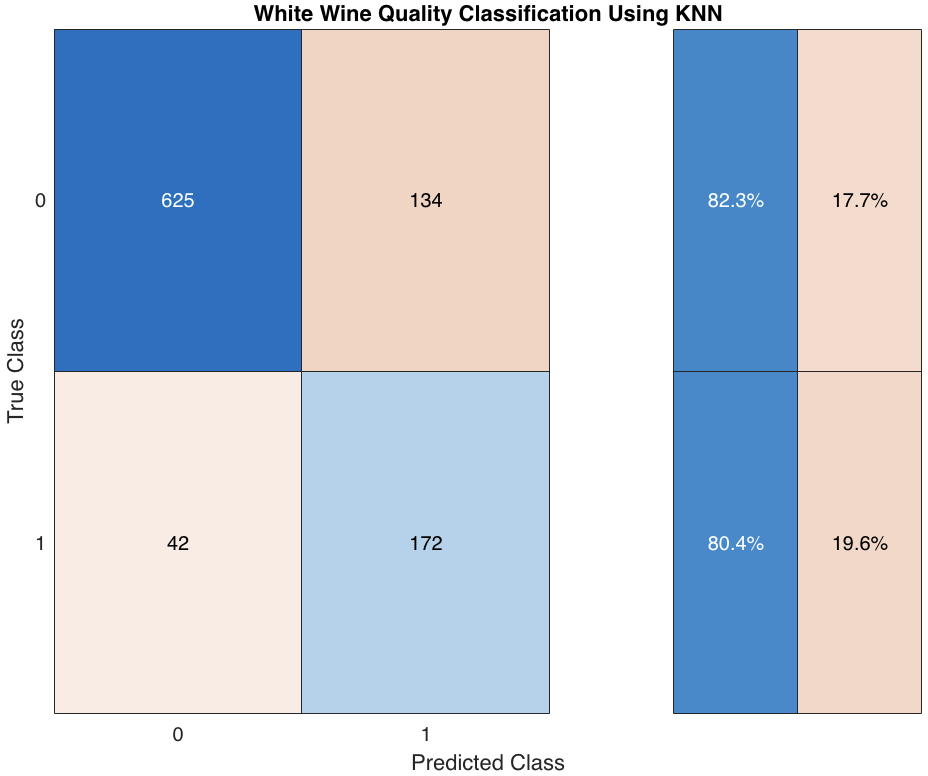

In conclusion, after taking into consideration all of the above, the better algorithm to use for the given Wine classification problem, is **K-Nearest Neighbour**.

**Save workspace**

%save("testModels","Mdl1","Mdl2","Xval","Yval")

## Test Models

Run this section to load the models and the test set, make predictions on the test set and calculate and show confusion matrices, Accuracies and F1 Scores.

**Load models and test sets**

load("testModels.mat")

**Random Forest**

Testloss = loss(Mdl1,Xval,Yval); %get loss
pred = predict(Mdl1,Xval); %get prediction
cm = confusionmat(Yval,pred); %create confusion matrix

%calculate precision, recall and f1 score
%inspired by https://youtu.be/5mVv2VocH2o
cmt = cm'; %transpose the matrix
diagonal = diag(cmt); %get diagonal of matrix

sum_of_rows = sum(cmt,2); %get sum of rows
sum_of_columns = sum(cmt,1); %get sum of columns

precision = diagonal ./ sum_of_rows; %get precision
overall_precision = mean(precision); %get overall precision

recall = diagonal ./ sum_of_columns'; %get recall
overall_recall = mean(recall); %get overall recall

RF_F1_score = 2 * ((overall_precision * overall_recall) / (overall_precision + overall_recall)) %get f1 score

RF_F1_score = 0.7760

RF_TestAcc = 100*(1-Testloss) %get test accuracy

RF_TestAcc = 80.9282

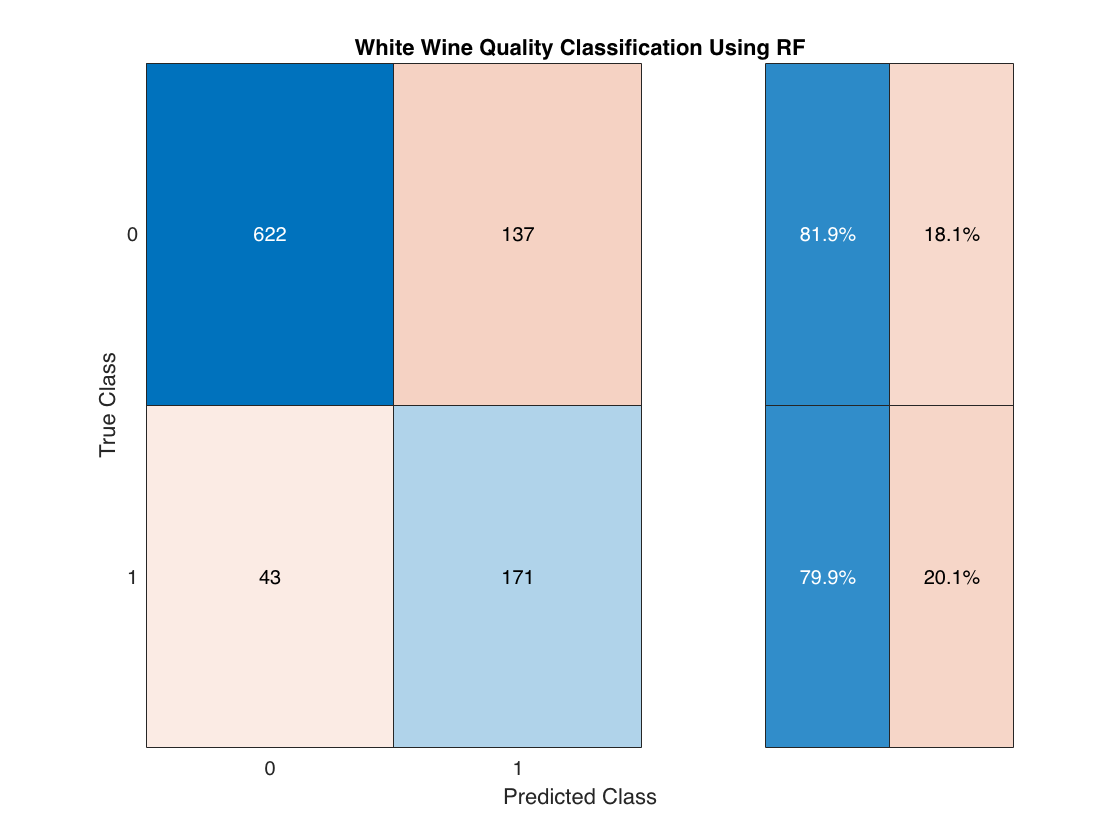

%show confusion matrix
cm = confusionchart(Yval,pred);
%set title
cm.Title = 'White Wine Quality Classification Using RF';
%Add column and row summaries
cm.RowSummary = 'row-normalized';

**K-Nearest Neighbour**

Testloss = loss(Mdl2,Xval,Yval); %get loss
pred = predict(Mdl2,Xval); %get prediction
cm = confusionmat(Yval,pred); %create confusion matrix

%calculate precision, recall and f1 score
%inspired by https://youtu.be/5mVv2VocH2o
cmt = cm'; %transpose the matrix
diagonal = diag(cmt); %get diagonal of matrix

sum_of_rows = sum(cmt,2); %get sum of rows
sum_of_columns = sum(cmt,1); %get sum of columns

precision = diagonal ./ sum_of_rows; %get precision
overall_precision = mean(precision); %get overall precision

recall = diagonal ./ sum_of_columns'; %get recall
overall_recall = mean(recall); %get overall recall

KNN_F1_score = 2 * ((overall_precision * overall_recall) / (overall_precision + overall_recall)) %get f1 score

KNN_F1_score = 0.7803

KNN_TestAcc = 100*(1-Testloss) %get test accuracy

KNN_TestAcc = 81.3595

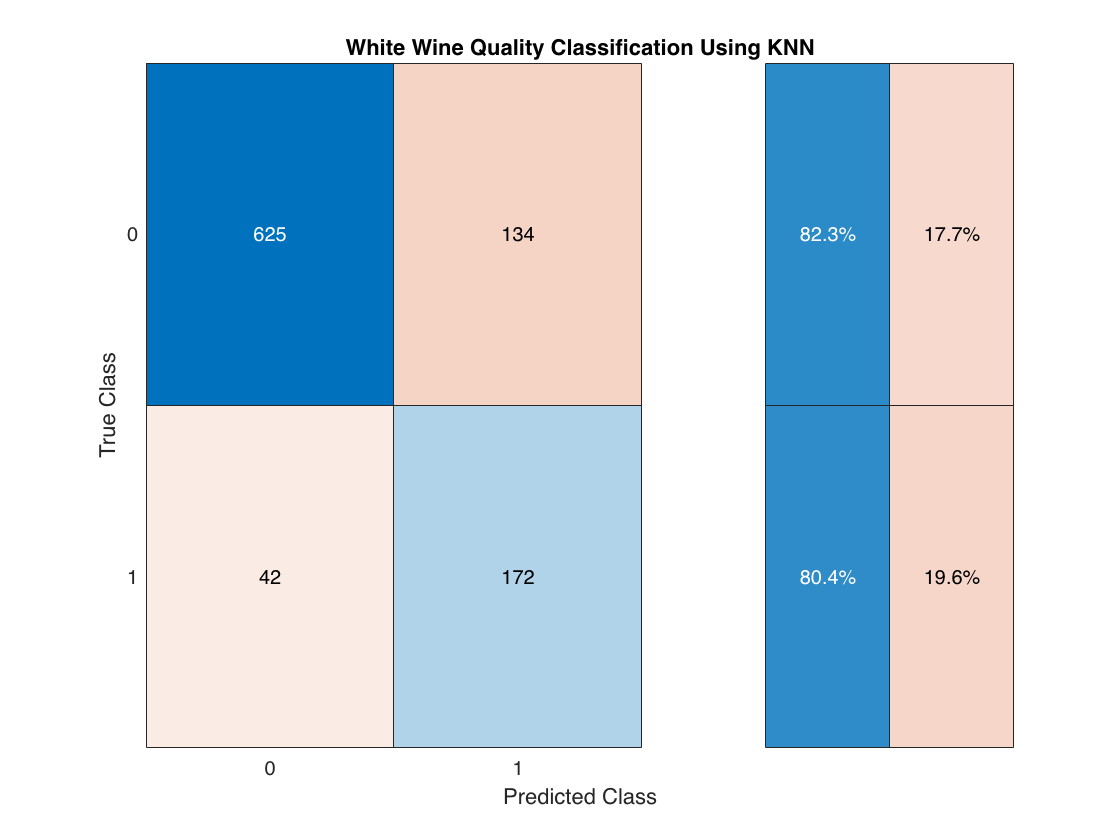

%show confusion matrix
cm = confusionchart(Yval,pred);
%set title
cm.Title = 'White Wine Quality Classification Using KNN';
%Add column and row summaries
cm.RowSummary = 'row-normalized';

**References:**

*1.*[*^*](about:blank<#M_46806054>)* P. Cortez, A. Cerdeira, F. Almeida, T. Matos and J. Reis. Modeling wine preferences by data mining from physicochemical properties. In Decision Support Systems, Elsevier, 47(4):547-553, 2009. Available at: [*[*Web Link*](https://www.sciencedirect.com/science/article/abs/pii/S0167923609001377?via%3Dihub)*] *

*2.*[*^*](about:blank<#H_5C4A9CDB>)* Breiman, L. Random Forests. Machine Learning ****45, ****5–32 (2001). *[*https://doi.org/10.1023/A:1010933404324*](https://doi.org/10.1023/A:1010933404324)

*3.*[*^*](about:blank<#M_D8C25AD2>)* Powers, David. (2008). Evaluation: From Precision, Recall and F-Factor to ROC, Informedness, Markedness & Correlation. Mach. Learn. Technol.. 2. Available at: [*[*Web Link*](https://www.researchgate.net/publication/228529307_Evaluation_From_Precision_Recall_and_F-Factor_to_ROC_Informedness_Markedness_Correlation)*]*

*4.*[*^*](about:blank<#M_2D84ADAF>)* Cawley, Gavin C.; Talbot, Nicola L. C. (2010). *[*"On Over-fitting in Model Selection and Subsequent Selection Bias in Performance Evaluation"*](http://www.jmlr.org/papers/volume11/cawley10a/cawley10a.pdf) ***11****. Journal of Machine Learning Research: 2079–2107.*

*5.*[*^*](about:blank<#H_38CC672F>)* Bishop, C.M. 2006, Nearest-neighbour methods. Pattern recognition and machine learning, Springer, New York.*